# **垂直跳び　床反力パワー分析**

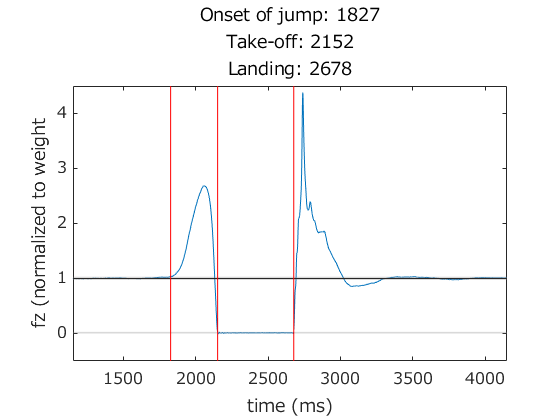

clear
close all
clc


% *** サンプルデータ を load ***
fileName = 'DemoDataSJ' ;
load(fileName) ;

% *** 実験実習で測定計測したデータ を load***
fileName = 'Data_S01' ; % ←　被験者番号を指定する
load(fileName) ;

Data = DataStruct.SJ(1) ; % ←　条件名・試行番号を指定する
grfs = Data.Forces ;
Markers = Data.Markers ;
% ****

% 図を作成して、床反力波形を確認
fz = grfs(:,3) + grfs(:,6) ;

% イベント検出
Prm.Alpha = 0.03 ;
Prm.Beta = 0.03 ;
Prm.Win = 50 ;

JumpEvent = detectJumpEvent(fz, Prm) ;
figJumpEvent(fz, Prm, JumpEvent) ;

※　記述はざっくりとしたもので、厳密性を欠きます…

## 運動方程式　位置・速度・加速度の関係

位置を1回時間微分したものが速度：　$v = \frac{dx}{dt}=\dot{x}$

速度を1回時間微分したもの（位置を2回微分したもの）が加速度：　$a = \frac{dv}{dt}=\ddot{x}$

加速度から速度・位置を得るためには、積分すればよい


$$v(t) = \int_0^t{a(t)}dt+v(0)$$



$$x(t) = \int_0^t{v(t)}dt+x(0)$$


## 数値積分　（高校数学IIIだと、区分求積）

ざっくり言うと、積分とは曲線下の面積を求めること。

曲線で囲まれた部分を、小さな長方形や台形と見做して足していくことでも、曲線下の面積は（だいたい）求められる

フォースプレートにより、床反力を  1 kHz で計測している（1 ms 毎に計測値がある）ので、

横幅 1 ms の小さな長方形/台形がたくさんあると考えて、面積を計算することができる

※　これを、"数値的に積分する" と言う。　（対義語は、解析的に～

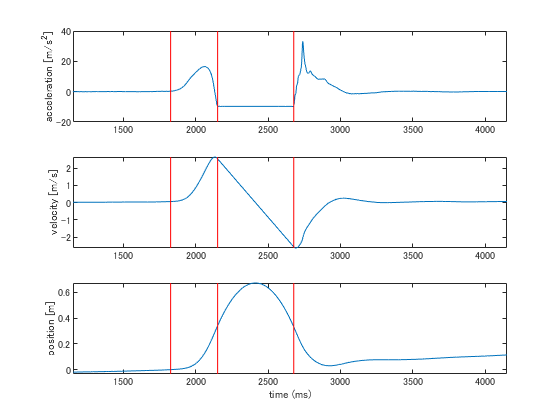

% fz = fz / mean(fz(1:1000)) ; % **** ドリフト補正 ****

z2Dot = (fz-1) * gravity ; % ここの fz が、体重で正規化された値であることに注意
zDot = cumtrapz(z2Dot) * 0.001 ; % cumtrapz: 累積台形積分を計算する関数
z = cumtrapz(zDot) * 0.001 ;
z = z - z(JumpEvent.OnsetJump) ; % onset of jump motion の時刻における位置を基準とする

figure
subplot(3,1,1) ;
plot(z2Dot)
ylabel('acceleration [m/s^2]')
lineplot([JumpEvent.OnsetJump, JumpEvent.TakeOff, JumpEvent.Landing],'v', 'r') ;
set(gca, 'xlim', [-1000,2000] + JumpEvent.TakeOff) ;

subplot(3,1,2) ;
plot(zDot)
ylabel('velocity [m/s]')
lineplot([JumpEvent.OnsetJump, JumpEvent.TakeOff, JumpEvent.Landing],'v', 'r') ;
set(gca, 'xlim', [-1000,2000] + JumpEvent.TakeOff) ;

subplot(3,1,3) ;
plot(z)
ylabel('position [m]')
lineplot([JumpEvent.OnsetJump, JumpEvent.TakeOff, JumpEvent.Landing],'v', 'r') ;
set(gca, 'xlim', [-1000,2000] + JumpEvent.TakeOff) ;
xlabel('time (ms)')


% ※注意　ドリフト：　フォースプレートの計測値が僅かにずれていた場合、位置が二次関数的に増加/減少することがある


## 仕事

ある物体に、外力 $F$ が作用し、位置が $\Delta x$ 変化したとき、

"外力 $F$ は、この物体に対して、$F\Delta x$ （単位: J）の仕事をした" と言い、

それに伴い、この物体の運動エネルギーは、$\Delta KE=\frac{1}{2}mv^2-\frac{1}{2}mv_0^2=F\Delta x$ だけ変化する

## パワー

パワー（仕事率）とは、単位時間当たりの仕事のことで、W = J/s の単位をもつ

従って、ある物体に、時間$\Delta t$の間、外力 $F$ が作用し、位置が$\Delta x$ 変化したときの仕事率は、 $\frac{F\Delta x}{\Delta t} = Fv$ で表される

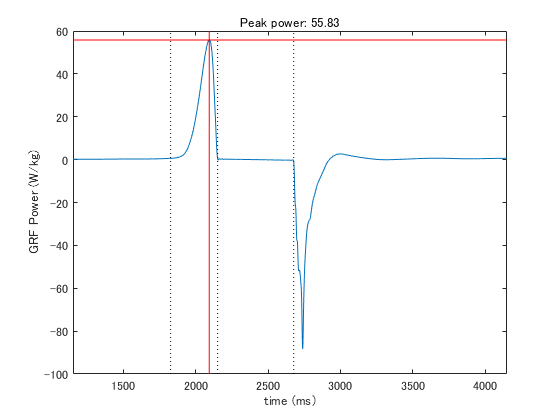


% power
grfPower = (fz*gravity) .* zDot ; % [N/bodyMass * m/s] = [J/s /bodyMass] = [W/bodyMass]

avgPower = mean(grfPower(JumpEvent.OnsetJump:JumpEvent.TakeOff)) ; % 動作開始から離地までの平均パワー
[peakPower, tPeakPower] = max(grfPower(JumpEvent.OnsetJump:JumpEvent.TakeOff)) ; % [W / kg] ### weight = m [kg] * g [m/s2]
tPeakPower = tPeakPower + JumpEvent.OnsetJump - 1 ;

figure
plot(grfPower) ;
lineplot([JumpEvent.OnsetJump, JumpEvent.TakeOff, JumpEvent.Landing],'v', 'k:') ;
lineplot(tPeakPower, 'v', 'r') ;
lineplot(peakPower, 'h', 'r') ;
set(gca, 'xlim', [-1000,2000] + JumpEvent.TakeOff) ;
ylabel('GRF Power (W/kg)')
xlabel('time (ms)')
title(sprintf('Peak power: %0.2f', peakPower))

## パワー分析部分も function にしておく

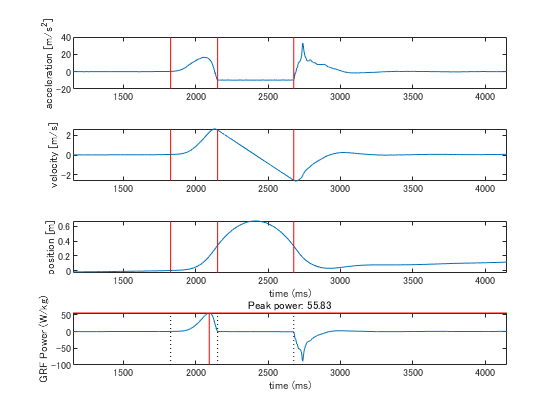


[GRFPower, PowerTimeSeries] = calculatePower(fz, JumpEvent) ;
figGRFPower(GRFPower, PowerTimeSeries, JumpEvent) ;

function JumpEvent = detectJumpEvent(fz, Prm)
    
    % パラメータ
    alpha = Prm.Alpha ;
    beta = Prm.Beta ;
    win = Prm.Win ;
    
    % イベント検出に共通しても用いる変数
    n = length(fz) ;
    baseFz = mean(fz(1:1000)) ; % 最初の1秒の平均値をベースラインとする　
                                %　なので、測定開始後1秒は静止していなければならない
    

    tOnsetJump = 0 ; % 変数の初期化
    for ii = 2:n-win
        % 条件１　ジャンプ開始時刻の直前の fz は、ベースライン±αの範囲内にある
        criteria1 = fz(ii-1) < baseFz*(1+alpha) && fz(ii-1) > baseFz*(1-alpha) ;
    
        % 条件２　ジャンプ開始時刻から win (ms)間、 fz は、ベースライン±α の範囲外にある
        criteria2 = all(fz(ii:ii+win) >= baseFz*(1+alpha)) || all(fz(ii:ii+win) <= baseFz*(1-alpha)) ;
    
        if criteria1 && criteria2 % 上記の2条件を同時に満たす
            tOnsetJump = ii ;
            break % 1回検出したら、ループを抜ける
        end
        
    end
    
    
    % takeoff
    tTakeOff = 0 ;
    for ii = 2:n-win
        if all( fz(ii:ii+win) < beta )
            tTakeOff = ii ;
            break
        end
    end
    
    % landing
    tLanding = 0 ;
    for ii = tTakeOff:n-win
        if all( fz(ii:ii+win) > beta )
            tLanding = ii ;
            break
        end
    end
    
    % output
    JumpEvent.OnsetJump = tOnsetJump ;
    JumpEvent.TakeOff = tTakeOff ;
    JumpEvent.Landing = tLanding ;
    
end


function figJumpEvent(fz, Prm, JumpEvent)
    
    % パラメータ
    alpha = Prm.Alpha ;
    beta = Prm.Beta ;
    win = Prm.Win ;
    
    % イベント検出に共通しても用いる変数
    n = length(fz) ;
    baseFz = mean(fz(1:1000)) ; % 最初の1秒の平均値をベースラインとする　
                                %　なので、測定開始後1秒は静止していなければならない
    
    % イベント時刻
    tOnsetJump = JumpEvent.OnsetJump ;
    tTakeOff = JumpEvent.TakeOff ;
    tLanding = JumpEvent.Landing ;
    
    % 図の作成
    figure
    plot(fz) ; % イベント検出に用いた時系列データ 
    
    % イベント検出に用いた閾値を図示　（※　進矢の自作関数を使っています
    lineplot(1, 'h', 'k') ; 
    arealine([baseFz-alpha, baseFz+alpha], 'h') ; 
    arealine([0, beta], 'h') ;
    
    % 検出されたイベントを図示
    lineplot([tOnsetJump, tTakeOff, tLanding], 'v', 'r') ;
    
    % 表示範囲を設定
    set(gca, 'xlim', [-1000, 2000]+tTakeOff)
    
    % 凡例等
    xlabel('time (ms)')
    ylabel('fz (normalized to weight')
    titleText = { sprintf('Onset of jump: %d', tOnsetJump) ;... % sprintf: 数値を文字列にフォーマットするときに用いる
                  sprintf('Take-off: %d', tTakeOff) ;...
                  sprintf('Landing: %d', tLanding) } ;
    title(titleText)
    set(gca, 'fontname', 'meiryo', 'fontsize', 12)

end


function [GRFPower, PowerTimeSeries] = calculatePower(fz, JumpEvent)
    
    % 数値積分
    z2Dot = (fz-1) * gravity ; % ここの fz が、体重で正規化された値であることに注意
    zDot = cumtrapz(z2Dot) * 0.001 ; % cumtrapz: 累積台形積分を計算する関数
    z = cumtrapz(zDot) * 0.001 ;
    z = z - z(JumpEvent.OnsetJump) ; % onset of jump motion の時刻における位置を基準とする
    
    PowerTimeSeries.Acc = z2Dot ;
    PowerTimeSeries.Vel = zDot ;
    PowerTimeSeries.Z = z ;
        
    % power
    grfPower = (fz*gravity) .* zDot ; % [N/bodyMass * m/s] = [J/s /bodyMass] = [W/bodyMass]
    PowerTimeSeries.GRFPower = grfPower ;
    
    avgPower = mean(grfPower(JumpEvent.OnsetJump:JumpEvent.TakeOff)) ; % 動作開始から離地までの平均パワー
    [peakPower, tPeakPower] = max(grfPower(JumpEvent.OnsetJump:JumpEvent.TakeOff)) ; % [W / kg] ### weight = m [kg] * g [m/s2]
    tPeakPower = tPeakPower + JumpEvent.OnsetJump - 1 ;
    
    GRFPower.AvgPower = avgPower ;
    GRFPower.PeakPower = peakPower ;
    GRFPower.tPeakPower = tPeakPower ;
    
    
end


function figGRFPower(GRFPower, PowerTimeSeries, JumpEvent)
    
    
    figure
    subplot(4,1,1) ;
    plot(PowerTimeSeries.Acc)
    ylabel('acceleration [m/s^2]')
    lineplot([JumpEvent.OnsetJump, JumpEvent.TakeOff, JumpEvent.Landing],'v', 'r') ;
    set(gca, 'xlim', [-1000,2000] + JumpEvent.TakeOff) ;
    
    subplot(4,1,2) ;
    plot(PowerTimeSeries.Vel)
    ylabel('velocity [m/s]')
    lineplot([JumpEvent.OnsetJump, JumpEvent.TakeOff, JumpEvent.Landing],'v', 'r') ;
    set(gca, 'xlim', [-1000,2000] + JumpEvent.TakeOff) ;
    
    subplot(4,1,3) ;
    plot(PowerTimeSeries.Z)
    ylabel('position [m]')
    lineplot([JumpEvent.OnsetJump, JumpEvent.TakeOff, JumpEvent.Landing],'v', 'r') ;
    set(gca, 'xlim', [-1000,2000] + JumpEvent.TakeOff) ;
    xlabel('time (ms)')
    
    subplot(4,1,4) ;
    plot(PowerTimeSeries.GRFPower) ;
    lineplot([JumpEvent.OnsetJump, JumpEvent.TakeOff, JumpEvent.Landing],'v', 'k:') ;
    lineplot(GRFPower.tPeakPower, 'v', 'r') ;
    lineplot(GRFPower.PeakPower, 'h', 'r') ;
    set(gca, 'xlim', [-1000,2000] + JumpEvent.TakeOff) ;
    ylabel('GRF Power (W/kg)')
    xlabel('time (ms)')
    title(sprintf('Peak power: %0.2f', GRFPower.PeakPower))



end

